3.9

(a) use lsim to simulate the response if the system input x(t) = cos(t)

t = linspace(0,20,1000);
A = [1,1];
B = 1;
x = cos(t);
y = lsim(B,A,x,t);
subplot(2,1,1)
plot(t(500:1000),x(500:1000));
xlabel("t(10≤t≤20)");
ylabel("x(t)");
subplot(2,1,2);
plot(t(500:1000),y(500:1000));
xlabel("t(10≤t≤20)");
ylabel('y(t)');

(b) creat the signal x2(t) = sigh(cos(t))

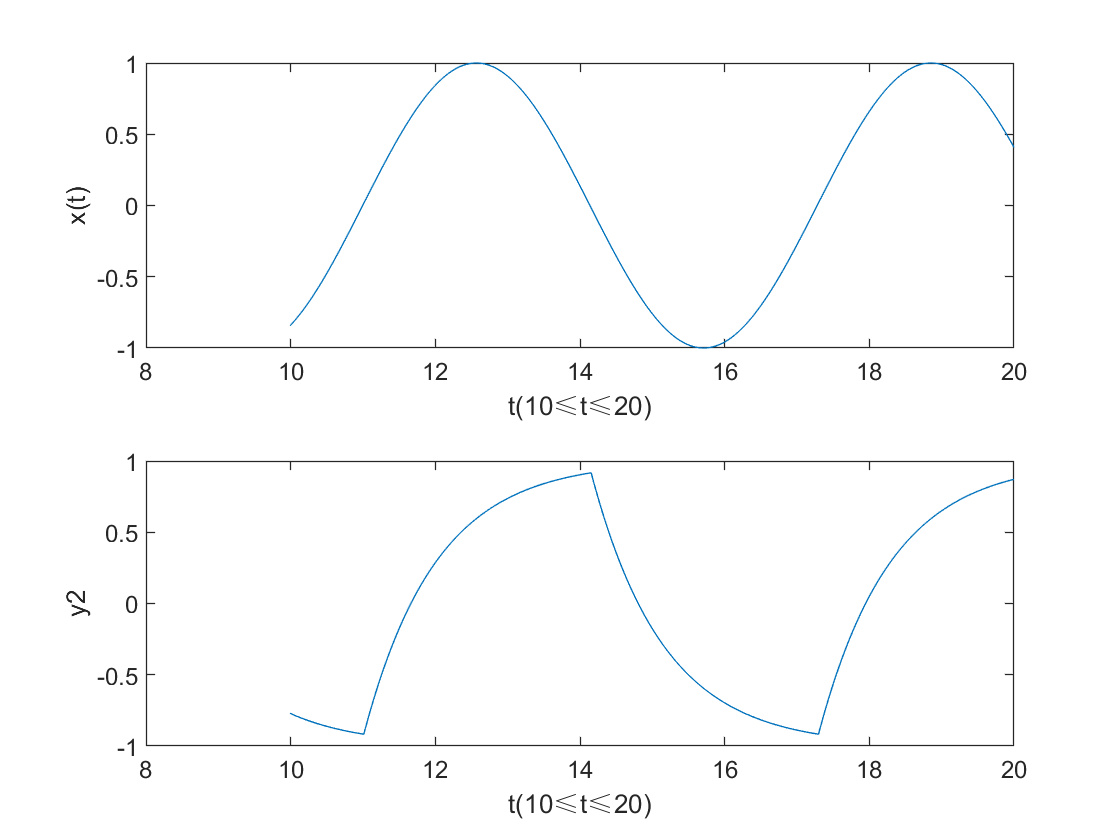

t=linspace(0,20,1000);
x2=cos(t);
x2(x2>0)=ones(size(x2(x2>0)));
x2(x2<0)=-ones(size(x2(x2<0)));
A=[1,1];
B=1;
y2=lsim(B,A,x2,t);
plot(t(500:1000),y2(500:1000))
xlabel("t(10≤t≤20)")
ylabel("y2");

(c)calculate the CTFS for square wave x2

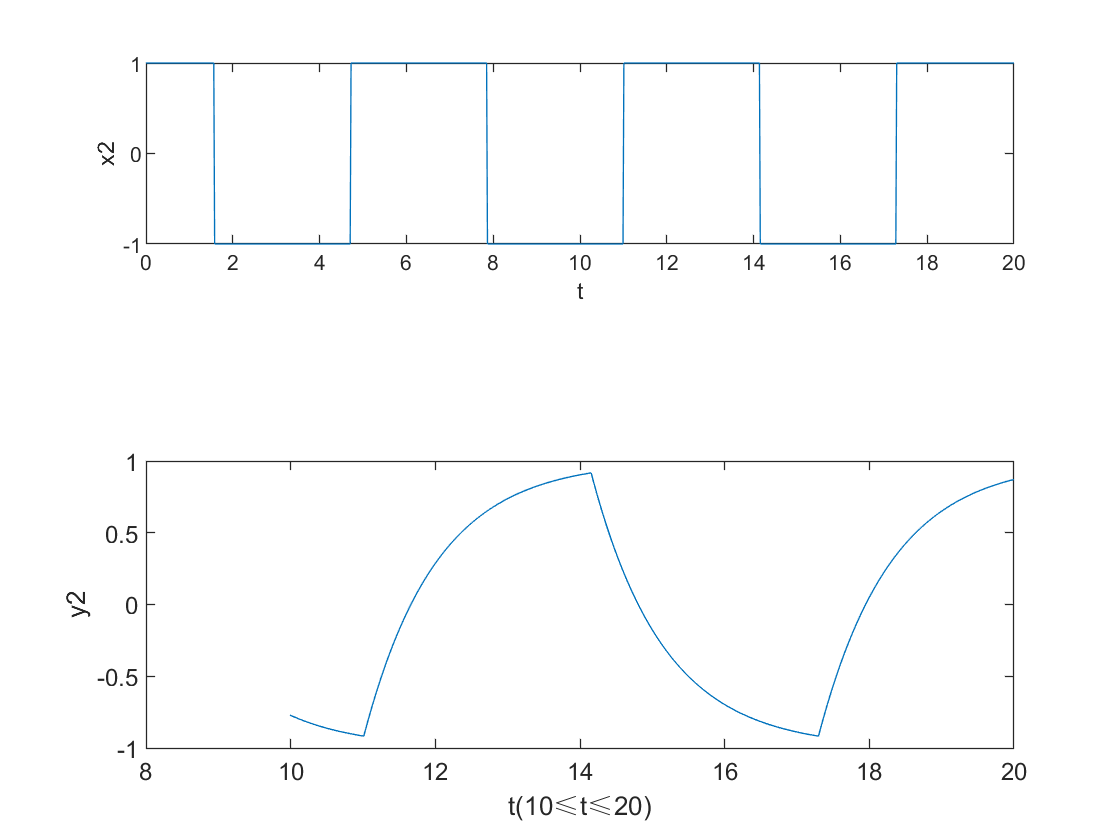

s1=2/pi*exp(1i*t)+2/pi*exp(-1i*t);
s2=-2/(3*pi)*exp(3i*t)-2/(3*pi)*exp(-3i*t);
s3=2/(5*pi)*exp(5i*t)+2/(5*pi)*exp(-5i*t);
s4=-2/(7*pi)*exp(7i*t)-2/(7*pi)*exp(-7i*t);
s5=2/(9*pi)*exp(9i*t)+2/(9*pi)*exp(-9i*t);
s=s1+s2+s3+s4+s5;
subplot(3,1,1)
plot(t,x2)
xlabel("t")
ylabel("x2");

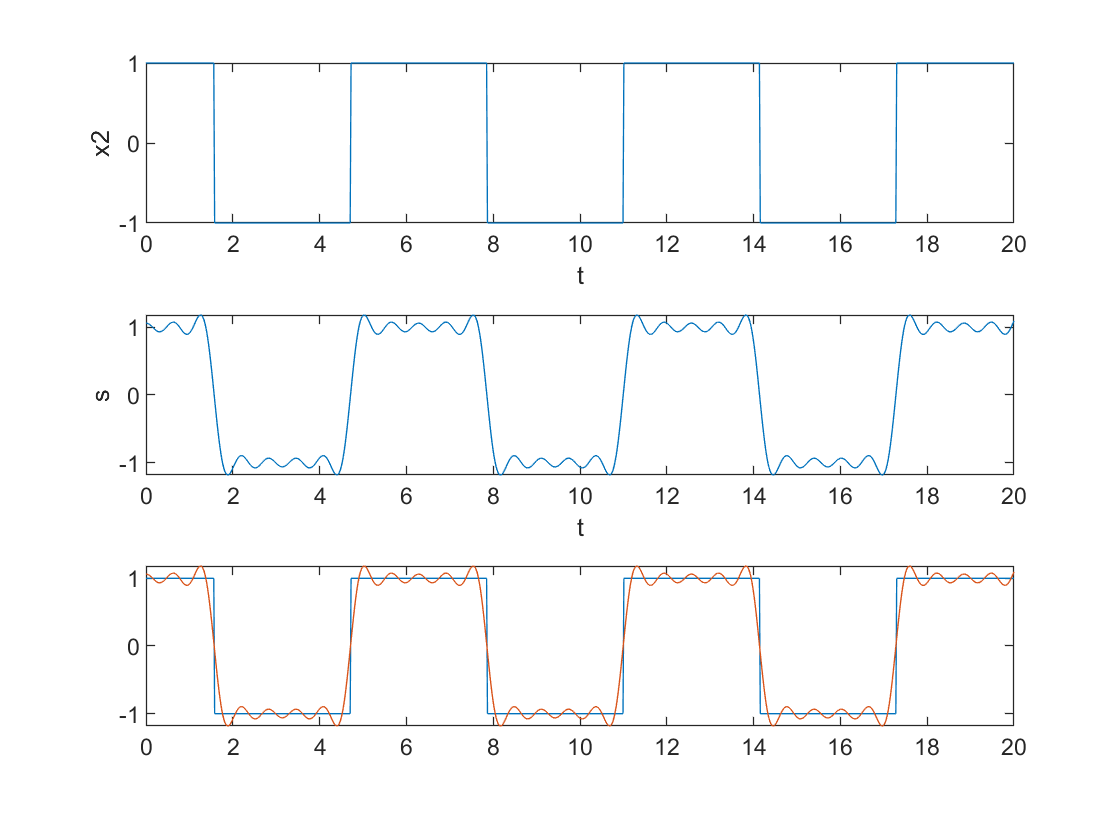

subplot(3,1,2)
plot(t,s)
xlabel("t")
ylabel("s");
subplot(3,1,3)
plot(t,x2);
hold on
plot(t,s);

(d) using lsim to find the responses y1-y5 to the signal s1-s5

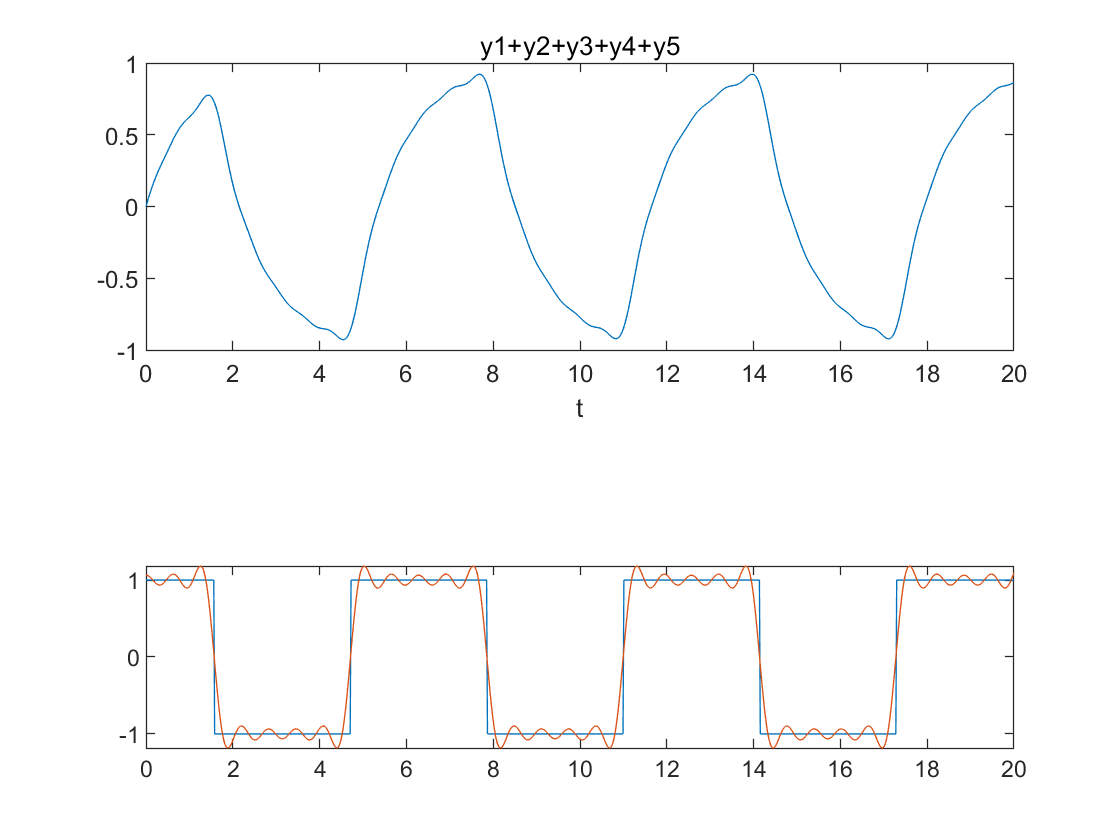

y1=lsim(B,A,s1,t);
y2=lsim(B,A,s2,t);
y3=lsim(B,A,s3,t);
y4=lsim(B,A,s4,t);
y5=lsim(B,A,s5,t);
y6=y1+y2+y3+y4+y5;
ys=lsim(B,A,s,t);
subplot(2,1,1)
plot(t,y6);
xlabel("t")
title("y1+y2+y3+y4+y5");

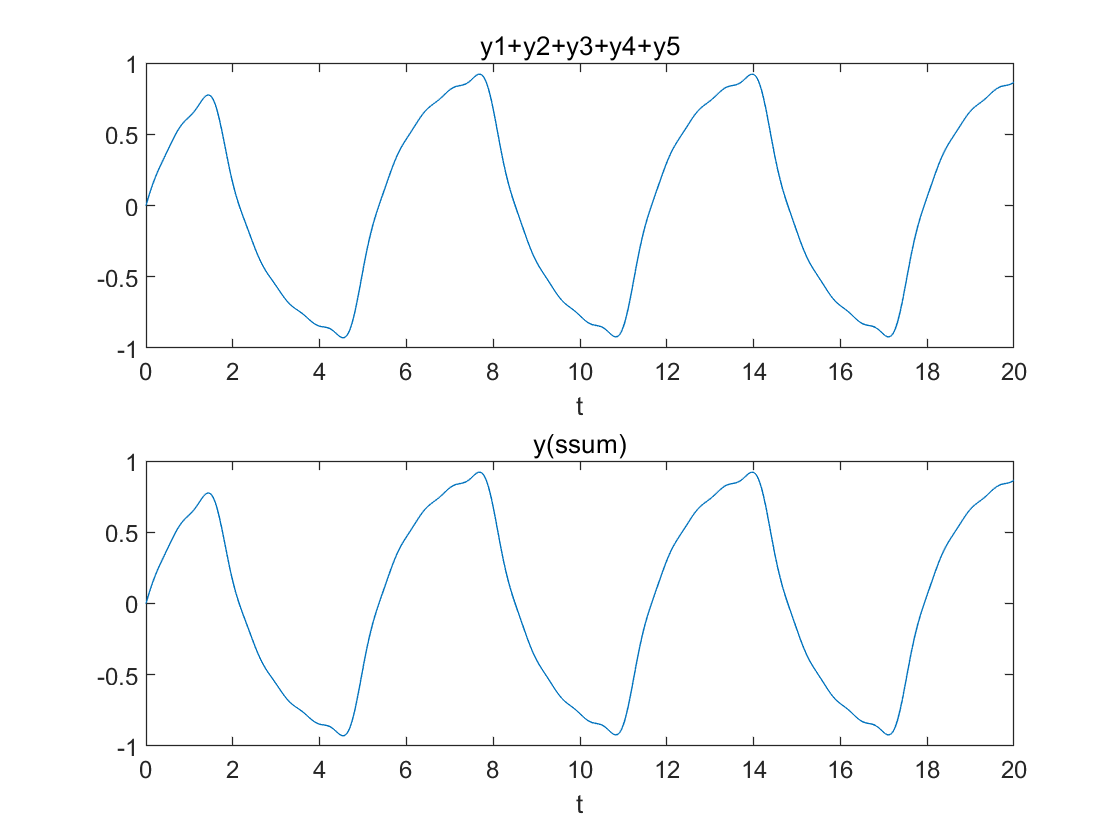

subplot(2,1,2)
plot(t,ys)
xlabel("t")
title("y(ssum)")

(e)compare the fig in (d) explain why they are similar

(f) vertify the signals y1-y5 are correct.

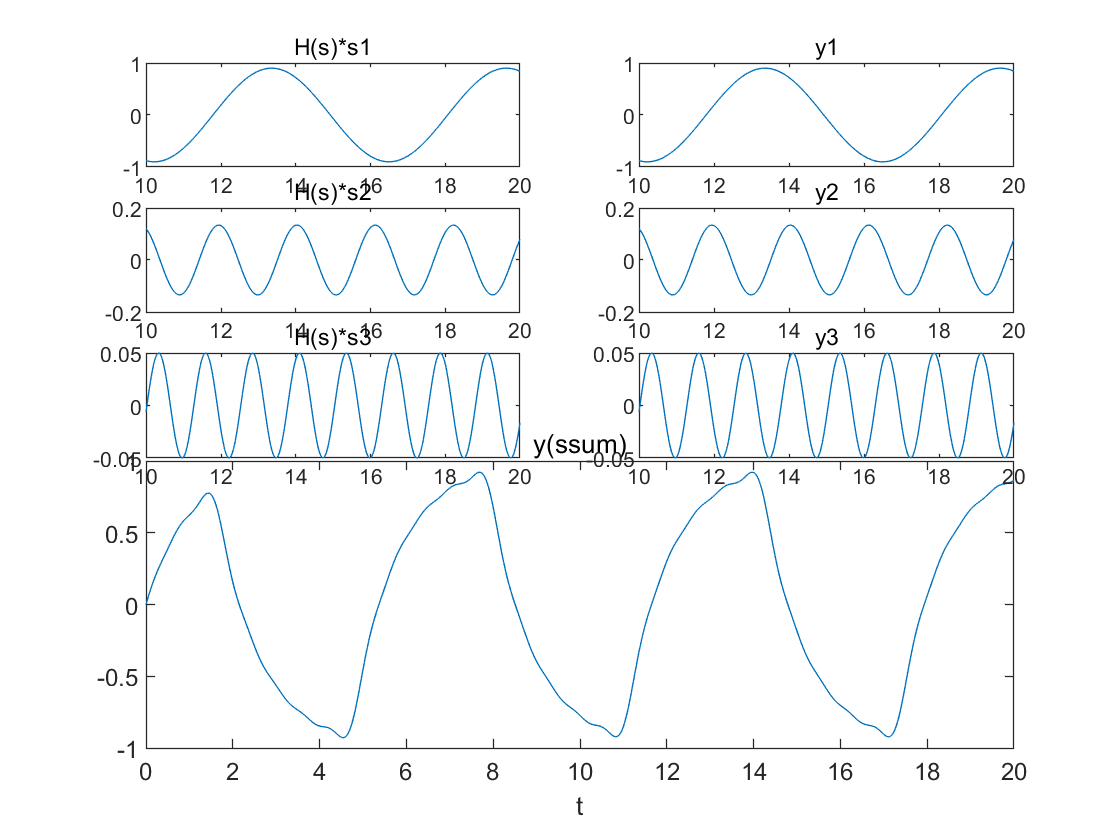

h1=2/pi*exp(1i*t)*1/(1+1i)+2/pi*exp(-1i*t)*1/(1-1i);
h2=-2/(3*pi)*exp(3i*t)*1/(1+3i)-2/(3*pi)*exp(-3i*t)*1/(1-3i);
h3=2/(5*pi)*exp(5i*t)*1/(1+5i)+2/(5*pi)*exp(-5i*t)*1/(1-5i);
h4=-2/(7*pi)*exp(7i*t)*1/(1+7i)-2/(7*pi)*exp(-7i*t)*1/(1-7i);
h5=2/(9*pi)*exp(9i*t)*1/(1+9i)+2/(9*pi)*exp(-9i*t)*1/(1-9i);
subplot(5,2,1)
plot(t(500:1000),h1(500:1000))
title("H(s)*s1");
subplot(5,2,2)
plot(t(500:1000),y1(500:1000))
title("y1");
subplot(5,2,3)
plot(t(500:1000),h2(500:1000))
title("H(s)*s2");
subplot(5,2,4)
plot(t(500:1000),y2(500:1000))
title("y2");
subplot(5,2,5)
plot(t(500:1000),h3(500:1000))
title("H(s)*s3");
subplot(5,2,6)
plot(t(500:1000),y3(500:1000))
title("y3");

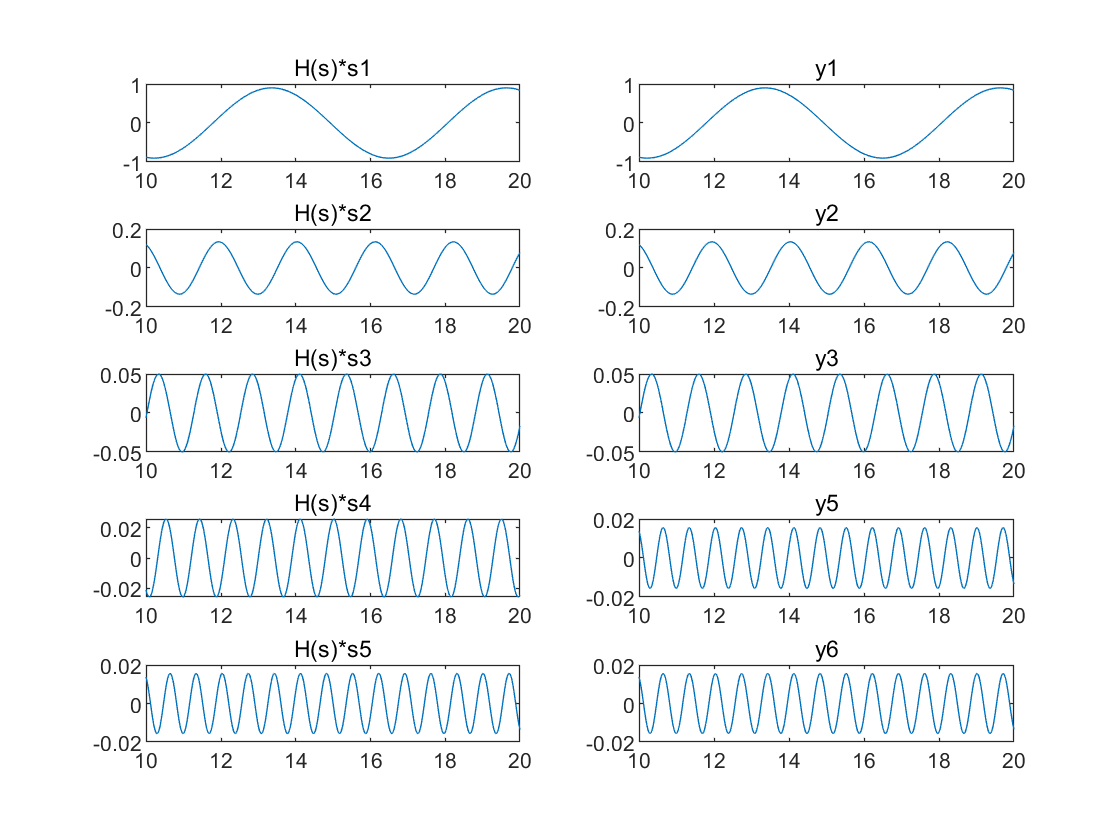

subplot(5,2,7)
plot(t(500:1000),h4(500:1000))
title("H(s)*s4");
subplot(5,2,8)
plot(t(500:1000),y5(500:1000))
title("y5")
subplot(5,2,9)
plot(t(500:1000),h5(500:1000))
title("H(s)*s5");
subplot(5,2,10)
plot(t(500:1000),y5(500:1000))
title("y6");